# Train DDPG Agent

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


Ts = 2; % every Ts seconds, the RL agent makes an action
Tf = 80; % episode length is seconds

mdl = "MODEL_SS_withSCCandRL_Emily";
open_system(mdl)

numAct = 4;
actInfo = rlNumericSpec([numAct 1],...
    'LowerLimit', -1*ones(numAct,1), ...
    'UpperLimit', ones(numAct,1));
actInfo.Name = 'Pagc';

numObs = 8*3;
obsInfo = rlNumericSpec([numObs 1],...
    'LowerLimit', -1*[0.5/60*ones(4,1); ones(4,1); Inf*ones(16,1)], ...
    'UpperLimit', 1*[0.5/60*ones(4,1); ones(4,1); Inf*ones(16,1)]);
obsInfo.Name = 'f, Ptie, Sf, df, SPtie, dPtie,';

agentblk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl, agentblk, obsInfo, actInfo);

## Create Agent

statePath = [
    featureInputLayer(numObs, Name="obsInput")
    fullyConnectedLayer(100)
    reluLayer
    fullyConnectedLayer(50, Name="fc1a")
    ];

actionPath = [
    featureInputLayer(numAct, Name="actInput")
    fullyConnectedLayer(50, Name="fc1b")
    ];

commonPath = [
    additionLayer(2, Name="add")
    reluLayer
    fullyConnectedLayer(50, Name="fc2")
    reluLayer
    fullyConnectedLayer(1, Name="Q")
    ];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"fc1a","add/in1");
criticNetwork = connectLayers(criticNetwork,"fc1b","add/in2");

criticNetwork = dlnetwork(criticNetwork);

rng(0,"twister");
criticNet = initialize(criticNetwork);
summary(criticNetwork)


   Initialized: true

   Number of learnables: 10.4k

   Inputs:
      1   'obsInput'   24 features
      2   'actInput'   4 features



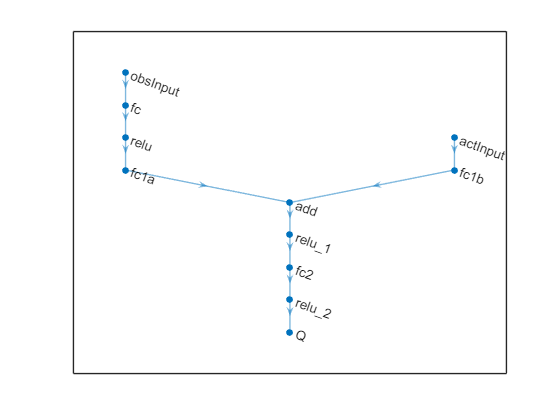

plot(criticNetwork);


critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsInput", ...
    ActionInputNames="actInput");

actorNet = [
    featureInputLayer(obsInfo.Dimension(1), Name="obsIn")
    fullyConnectedLayer(100)
    reluLayer()
    fullyConnectedLayer(50)
    tanhLayer()
    fullyConnectedLayer(actInfo.Dimension(1))
    ];

rng(0,"twister");
actorNet = dlnetwork(actorNet);
summary(actorNet)


   Initialized: true

   Number of learnables: 7.7k

   Inputs:
      1   'obsIn'   24 features



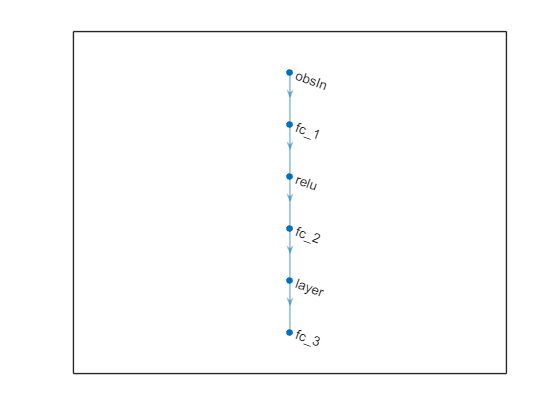

plot(layerGraph(actorNet));


actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo,...
        ObservationInputNames="obsIn");

criticOpts = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);
actorOpts = rlOptimizerOptions(LearnRate=1e-04,GradientThreshold=1);
agentOpts = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    CriticOptimizerOptions=criticOpts,...
    ActorOptimizerOptions=actorOpts,...
    ExperienceBufferLength=1e6,...
    DiscountFactor=0.999,...
    MiniBatchSize=64);
agentOpts.NoiseOptions.StandardDeviation = 0.1;
agentOpts.NoiseOptions.StandardDeviationDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

maxepisodes = 2000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    ScoreAveragingWindowLength=100,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=1e3);
rng(0,"twister");

doTraining = true;
if doTraining
    trainResult = train(agent, env, trainOpts);
% else
    % load("RLAgent.mat","agent")
end

## Simulate Agent

sim(mdl);


% Save the training result to a .mat file
save('BaseRLAgent.mat', 'trainResult');